## Methods

As introduced in `README2.md`, one model and one solver are requested. The model we chosen is DBFs, the key is to get a F matrix, which is achieved in `GetDBFmatrix.m` file.

The solver we used in this method is `lsqnoneg.`

help lsqnonneg

lsqnonneg - 解算非负线性最小二乘问题

    此 MATLAB 函数 返回在 x ≥ 0 的约束下，使得 norm(C*x-d) 最小的矢量 x。参数 C 和 d 必须为实数。

    x = lsqnonneg(C,d)
    x = lsqnonneg(C,d,options)
    x = lsqnonneg(problem)
    [x,resnorm,residual] = lsqnonneg(___)
    [x,resnorm,residual,exitflag,output] = lsqnonneg(___)
    [x,resnorm,residual,exitflag,output,lambda] = lsqnonneg(___)

    See also <a href="https://www.mathworks.com/help/releases/R2017a/matlab/ref/mldivide.html">mldivide</a>, <a href="https://www.mathworks.com/help/releases/R2017a/matlab/ref/optimset.html">optimset</a>

    Reference page for lsqnonneg



## Experiments

- In order to investigate the accuracy of this method, simulated datasets were constructed, a 16*16*1*61 dataset including 4 diffusion types was generated by `MysimData.m` script. The diffsion of each voxel is shown as below:

  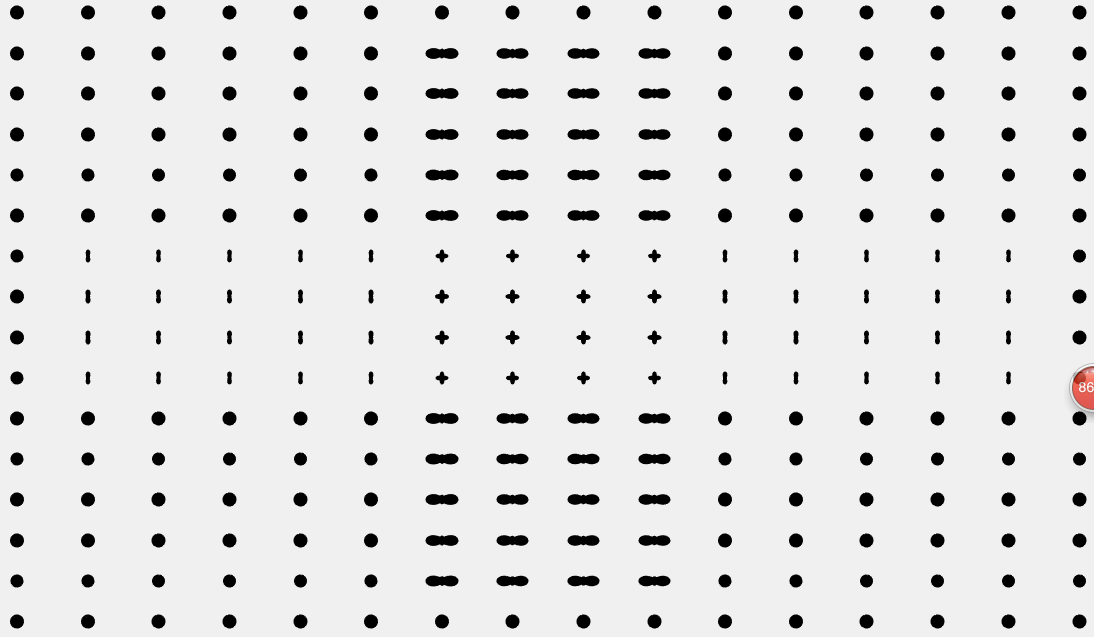

- The glyphs were drwan with `drawSpherical.m` script.

## Problems

- In registration, the normalize & write module provided by spm is inappropriate for 4D image, so I writed `wMat_resample_based_Def_demo `to implement it.